# **fourth Optimal Control Project**

# **Designing a Discrete-Time LQG Controller with a Steady-State Kalman Filter under White Process and Measurement Noise.**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

## Parameters

clear all
close all
clc

g = 9.8;
m = 0.65;
Ix = 7.5e-3;
Iy = 7.5e-3;
Iz = 1.3e-2;

## Continuous-time linearized system

A = [0 1 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 g 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 g 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 1;
     0 0 0 0 0 0 0 0 0 0 0 0];

B = [0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     1/m 0 0 0;
     0 0 0 0;
     0 1/Ix 0 0;
     0 0 0 0;
     0 0 1/Iy 0;
     0 0 0 0;
     0 0 0 1/Iz];

C = [1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0];

D = zeros(size(C,1),size(B,2));

## Discretization

Ts = 0.001;
sys_c = ss(A, B, C, D);
sys_d = c2d(sys_c, Ts);
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;

## Noise covariances

Q_w = 8e-6*eye(4);
R_v = 1e-5*eye(6);
gama_w = Bd;

## LQR controller

Q = diag([2000 1 2000 1 2000 1 1 1 1 1 1 1]);
R = 0.01 * eye(4);
[Kd,~,~] = dlqr(Ad, Bd, Q, R);

## Simulation setup

T_end = 50;
N = round(T_end / Ts);
x = zeros(12, N);
xh = zeros(12, N);
u = zeros(4, N);
r = zeros(12, N);
y = zeros(6, N);
t = (0:N-1)*Ts;

xod = 0.5 * cos(t/2);
yod = 0.5 * sin(t/2);
zod = -1 - t/10;
r(1,:) = xod;
r(3,:) = yod;
r(5,:) = zod;

## Kalman filter design

[Pk,~,~] = dare(Ad',Cd',gama_w*Q_w*gama_w',R_v);
Kk = Pk * Cd' / (Cd * Pk * Cd' + R_v);

x0 = zeros(12,1);
xh(:,1) = x0;

w = zeros(4, N);
v = zeros(6, N);
z = zeros(6, N);
r_dot = zeros(12, N);

Bpinv = pinv(Bd); 

r_dot(:,2:N) = (r(:,2:N) - r(:,1:N-1)) / Ts;

for i = 1:N-1
    
    w(:,i) = randn(4,1);       
    v(:,i) = randn(6,1);       

    x(:,i+1) = Ad * x(:,i) + Bd * u(:,i) + gama_w * w(:,i);

    z(:,i) = Cd * x(:,i) + v(:,i);  
    y(:,i) = Cd * x(:,i);          

    x_pred = Ad * xh(:,i) + Bd * u(:,i);
    y_pred = Cd * x_pred;
    xh(:,i+1) = x_pred + Kk * (z(:,i) - y_pred);

    u(:,i+1) = -Kd * (xh(:,i+1) - r(:,i+1)) + Bpinv * (r_dot(:,i+1) - Ad * r(:,i+1));
end

## Figure 1: Positions x, y, z (with references and estimates)

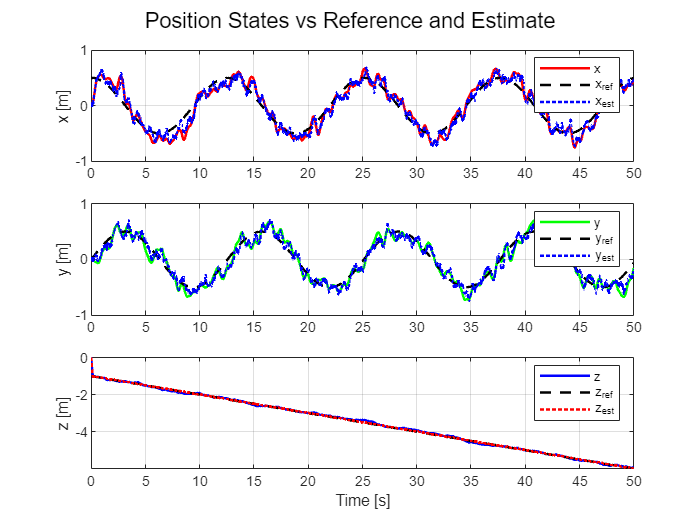

x = x'; xh = xh'; r = r'; 
t = t(:); 

figure;
subplot(3,1,1);
plot(t, x(:,1), 'r', t, r(:,1), 'k--', t, xh(:,1), 'b:', 'LineWidth', 1.5);
ylabel('x [m]'); legend('x', 'x_{ref}', 'x_{est}'); grid on;

subplot(3,1,2);
plot(t, x(:,3), 'g', t, r(:,3), 'k--', t, xh(:,3), 'b:', 'LineWidth', 1.5);
ylabel('y [m]'); legend('y', 'y_{ref}', 'y_{est}'); grid on;

subplot(3,1,3);
plot(t, x(:,5), 'b', t, r(:,5), 'k--', t, xh(:,5), 'r:', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('z [m]'); legend('z', 'z_{ref}', 'z_{est}'); grid on;
sgtitle('Position States vs Reference and Estimate');

## Figure 2: Velocities ẋ, ẏ, ż (with estimates)

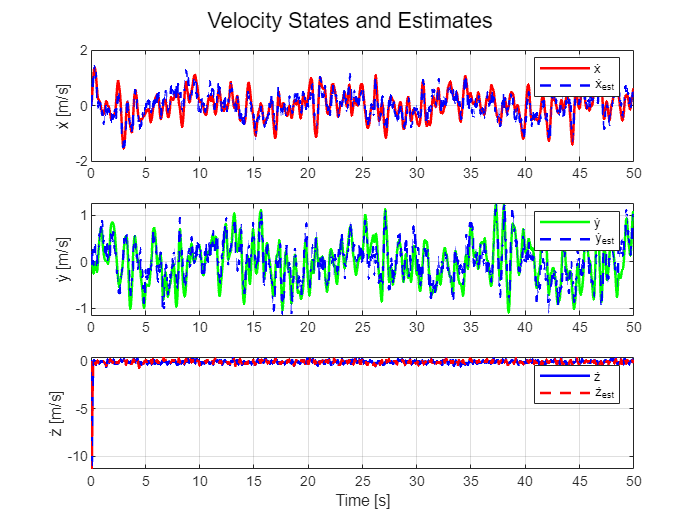

figure;
subplot(3,1,1);
plot(t, x(:,2), 'r', t, xh(:,2), 'b--', 'LineWidth', 1.5);
ylabel('ẋ [m/s]'); legend('ẋ', 'ẋ_{est}'); grid on;

subplot(3,1,2);
plot(t, x(:,4), 'g', t, xh(:,4), 'b--', 'LineWidth', 1.5);
ylabel('ẏ [m/s]'); legend('ẏ', 'ẏ_{est}'); grid on;

subplot(3,1,3);
plot(t, x(:,6), 'b', t, xh(:,6), 'r--', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('ż [m/s]'); legend('ż', 'ż_{est}'); grid on;
sgtitle('Velocity States and Estimates');

## Figure 3: Euler Angles φ, θ, ψ (with estimates)

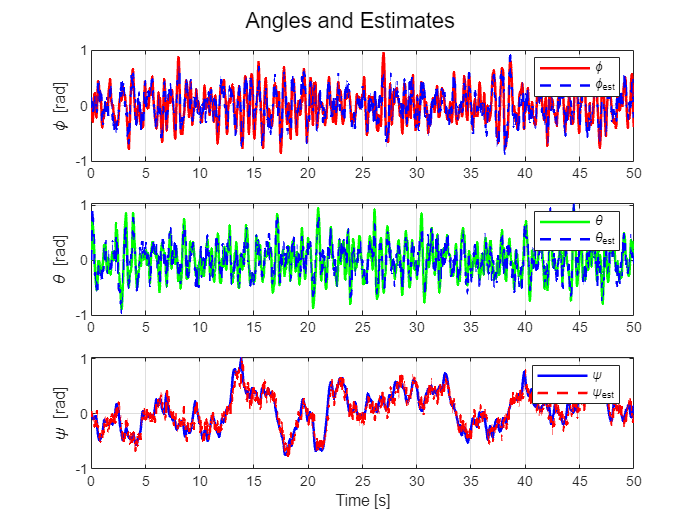

figure;
subplot(3,1,1);
plot(t, x(:,7), 'r', t, xh(:,7), 'b--', 'LineWidth', 1.5);
ylabel('\phi [rad]'); legend('\phi', '\phi_{est}'); grid on;

subplot(3,1,2);
plot(t, x(:,9), 'g', t, xh(:,9), 'b--', 'LineWidth', 1.5);
ylabel('\theta [rad]'); legend('\theta', '\theta_{est}'); grid on;

subplot(3,1,3);
plot(t, x(:,11), 'b', t, xh(:,11), 'r--', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('\psi [rad]'); legend('\psi', '\psi_{est}'); grid on;
sgtitle('Angles and Estimates');

## Figure 4: Angular Velocities φ̇, θ̇, ψ̇ (with estimates)

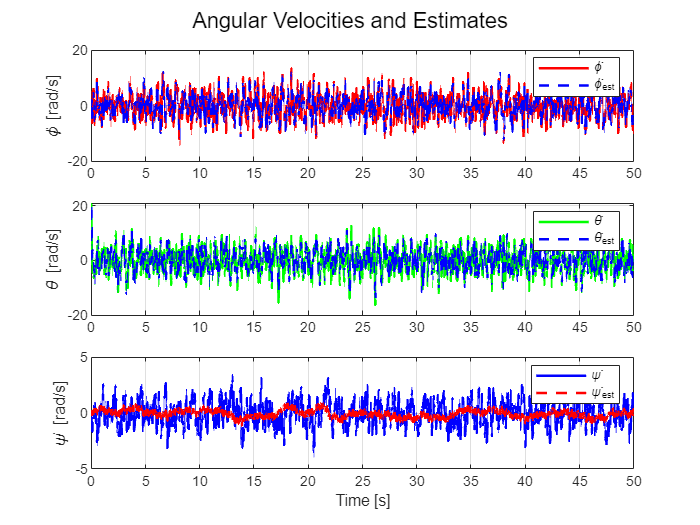

figure;
subplot(3,1,1);
plot(t, x(:,8), 'r', t, xh(:,8), 'b--', 'LineWidth', 1.5);
ylabel('\phi̇ [rad/s]'); legend('\phi̇', '\phi̇_{est}'); grid on;

subplot(3,1,2);
plot(t, x(:,10), 'g', t, xh(:,10), 'b--', 'LineWidth', 1.5);
ylabel('\thetȧ [rad/s]'); legend('\thetȧ', '\thetȧ_{est}'); grid on;

subplot(3,1,3);
plot(t, x(:,12), 'b', t, xh(:,12), 'r--', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('\psi̇ [rad/s]'); legend('\psi̇', '\psi̇_{est}'); grid on;
sgtitle('Angular Velocities and Estimates');

## 3D Trajectory Plot

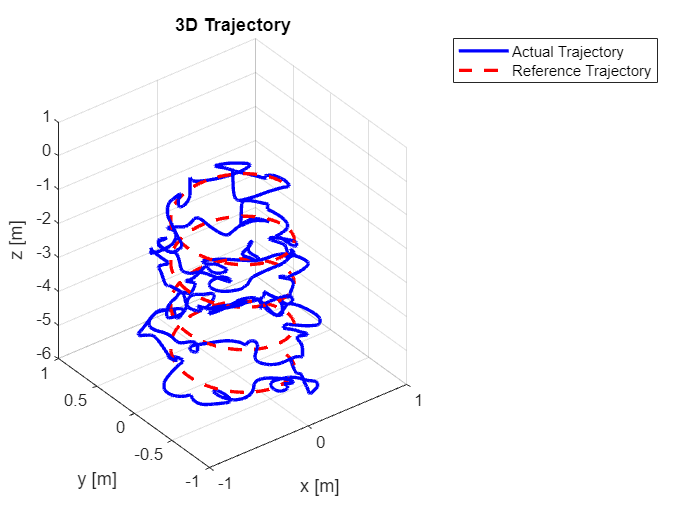

figure;
plot3(x(:,1), x(:,3), x(:,5), 'b', 'LineWidth', 2); hold on;
plot3(r(:,1), r(:,3), r(:,5), 'r--', 'LineWidth', 2);
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]');
legend('Actual Trajectory', 'Reference Trajectory');
grid on; title('3D Trajectory'); view(3);

## Figure 5: Tracking Error in x, y, z

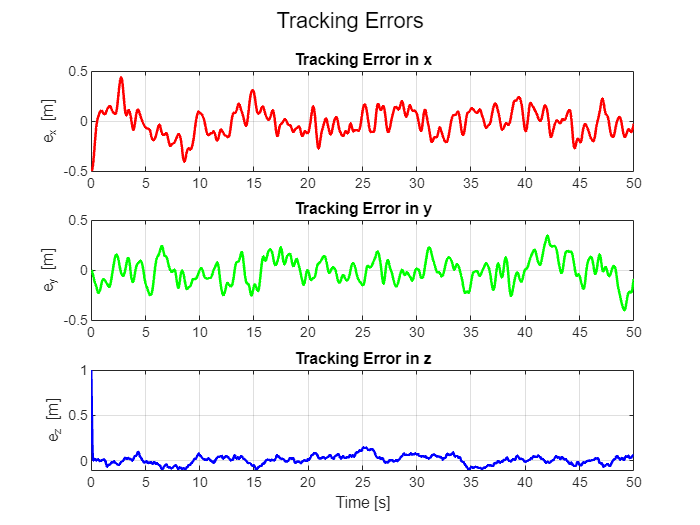

ex = x(:,1) - r(:,1);
ey = x(:,3) - r(:,3);
ez = x(:,5) - r(:,5);

figure;
subplot(3,1,1);
plot(t, ex, 'r', 'LineWidth', 1.5);
ylabel('e_x [m]'); grid on; title('Tracking Error in x');

subplot(3,1,2);
plot(t, ey, 'g', 'LineWidth', 1.5);
ylabel('e_y [m]'); grid on; title('Tracking Error in y');

subplot(3,1,3);
plot(t, ez, 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('e_z [m]'); grid on; title('Tracking Error in z');

sgtitle('Tracking Errors');

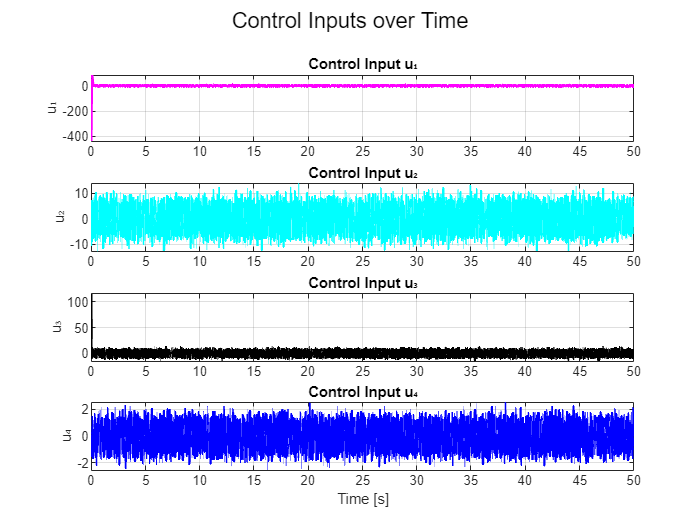

figure;
subplot(4,1,1);
plot(t, u(1,:), 'm', 'LineWidth', 1.5);
ylabel('u₁'); title('Control Input u₁'); grid on;

subplot(4,1,2);
plot(t, u(2,:), 'c', 'LineWidth', 1.5);
ylabel('u₂'); title('Control Input u₂'); grid on;

subplot(4,1,3);
plot(t, u(3,:), 'k', 'LineWidth', 1.5);
ylabel('u₃'); title('Control Input u₃'); grid on;

subplot(4,1,4);
plot(t, u(4,:), 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('u₄'); title('Control Input u₄'); grid on;

sgtitle('Control Inputs over Time');